# Dual-pixel autofocus sensor simulation

We illustrate how to create a dual pixel sensor for autofocus applications.  

The dual pixel design consists of a sensor with rectangular pixels that are twice as high as wide (see below).  There is a microlens over each pixel that directs light from the left half of the lens to the right pixel, and right half of the lens to the left pixel. This forms two independent images, seen through the right and left side of the lens.   

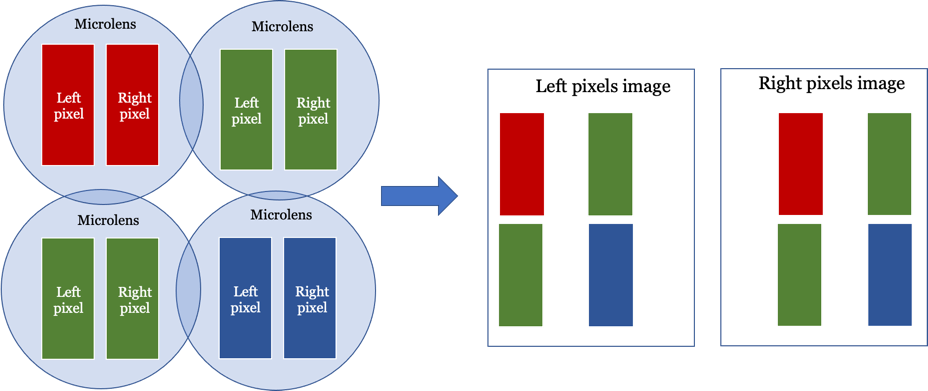

In regions where the focus is good, the left and right images have the same value.  But in regions where there is defocus, the left and right images do not have the same value.  

Using signal processing methods, we can detect the regions where the left and right image values are the same.  By adjusting the distance of the sensor from the lens, we make different regions in the left and right image match.  By choosing which regions match, we focusing that region of the image.

**See also:**

  s_sensorDPAF (ISETCam), tls_casmeraLightField.mlx

## Initialize

ieInit;
chdir(fullfile(piRootPath,'local'));

## Read the chess set scene

% thisR = piRecipeDefault('scene name','chessSet');
thisDB = isetdb;
sceneName = 'ChessSet';
thisScene = thisDB.contentFind('PBRTResources', 'name',sceneName);

thisR = piRead(thisScene,'docker',isetdocker);

[INFO]: Use a database scene: [/acorn/data/iset/PBRTResources/scene/ChessSet/ChessSet.pbrt].


[INFO]: Uploading data:
[INFO]: Sent 2702 bytes  received 620 bytes  6644.00 bytes/sec
[INFO]: Data uploaded successfully.
[INFO]: USE Docker: docker  --context remote-orange exec -it  pbrt-gpu-zhenyi14162 sh -c " pbrt  --gpu  --outfile /home/zhenyiliu/ISETRemoteRender/ChessSet/renderings/ChessSet.exr /home/zhenyiliu/ISETRemoteRender/ChessSet/ChessSet.pbrt "
[INFO]: Rendered remotely in: 11.33 sec
[INFO]: Downloading data:
[INFO]: Sent 32564 bytes  received 428438 bytes  922004.00 bytes/sec
[INFO]: Data downloaded successfully.
[INFO]: Output file:  renderings/ChessSet.exr


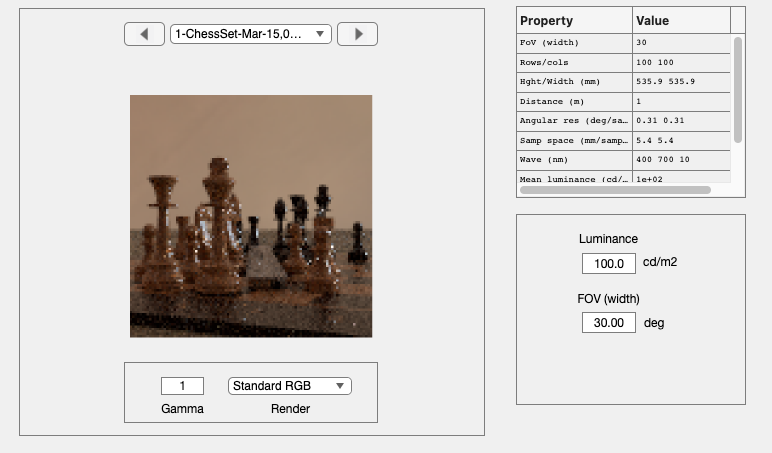

thisR.set('render type',{'radiance','depth'});
scene = piWRS(thisR);

dRange = sceneGet(scene,'depth range');   % Runs the docker to get the depth map

### Show just the imaging lens

iLensName = 'dgauss.22deg.3.0mm.json';  % Imaging lens
camera = piCameraCreate('omni','lens file',iLensName);
thisR.set('camera',camera);
thisR.set('film diagonal',4);
thisR.set('focus distance',2*dRange(2));

[INFO]: Uploading data:
[INFO]: Sent 3370 bytes  received 642 bytes  8024.00 bytes/sec
[INFO]: Data uploaded successfully.
[INFO]: USE Docker: docker  --context remote-orange exec -it  pbrt-gpu-zhenyi14162 sh -c " pbrt  --gpu  --outfile /home/zhenyiliu/ISETRemoteRender/ChessSet/renderings/ChessSet.exr /home/zhenyiliu/ISETRemoteRender/ChessSet/ChessSet.pbrt "
[INFO]: Rendered remotely in: 12.46 sec
[INFO]: Downloading data:
[INFO]: Sent 3722 bytes  received 449203 bytes  905850.00 bytes/sec
[INFO]: Data downloaded successfully.
[INFO]: Output file:  renderings/ChessSet.exr


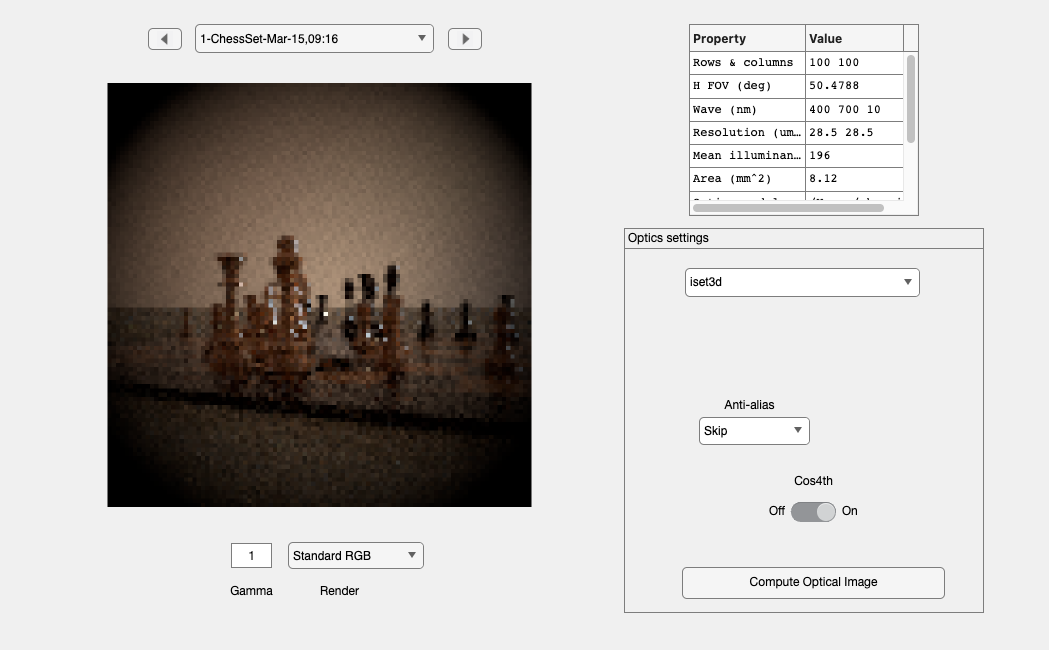

piWRS(thisR);

## Set up the combined imaging and microlens array

Make sure you have isetlens on your path!

uLensName = 'microlens.json';           % Microlens model

% The pixel width (below) is 1.4 um. The microlens covers two pixels
uLensDiameter = 0.0028;         % 2.8 um - each covers the dual pixels
nMicrolens    = 4*[128 128];      % There will be this many dual pixels

[combinedLensFile, info] = piMicrolensInsert(uLens,iLens,'n microlens',nMicrolens);

Unrecognized function or variable 'uLens'.

%[combinedLensFile, uLens, iLens] = lensCombine(uLensName,iLensName,uLensDiameter,nMicrolens);
camera = piCameraCreate('omni','lensFile',combinedLensFile);
thisR.set('camera',camera);

## Set up the film parameters

We want the OI to have adequate spatial resolution.  We set it up here to calculate the irradiance at 4 positions for each microlens, and thus two positions for each of the pixels. The pair of up/down positions will be summed by the sensor into a single pixel response. The pair of left/right positions will be used to calculate the signal incident at the two pixels behind the microlens.

pixelsPerMicrolens = 2;
halfPixelWidth_mm = uLens.get('lens diameter')/pixelsPerMicrolens;    % mm

% The total film (sensor) size.
filmwidth  = nMicrolens(2)*uLens.get('diameter','mm');       % mm
filmheight = nMicrolens(1)*uLens.get('diameter','mm');       % mm
filmresolution = [filmheight, filmwidth]/halfPixelWidth_mm;

% This is the size of the film/sensor in millimeters
thisR.set('film diagonal',sqrt(filmwidth^2 + filmheight^2));

% Film resolution -
thisR.set('film resolution',filmresolution);

% The desired spacing is halfPixelWidth_mm 
assert(thisR.get('sample spacing') - halfPixelWidth_mm < 1e-6);

% This is the aperture of the imaging lens of the camera in mm
thisR.set('aperture diameter',10);

% Adjust for quality
thisR.set('rays per pixel',1024);


## Render

Write, render, and show the recipe.  The optical image is returned in oi.  We also confirm that the spatial samples in the oi will match the resolution of the sensor pixels.

[oi, s] = piWRS(thisR);
ss = oiGet(oi,'sample spacing','mm');
assert(abs(ss(1) - halfPixelWidth_mm) < 10*eps);

## Make a dual pixel sensor that has rectangular pixels

sensor = sensorCreate('dual pixel',[],oi,nMicrolens);

## Compute the sensor data

Notice that we display the spatial structure of the image correctly, even though the pixels are rectangular.  That is magical programming behind the scene, where we know that the pixels are rectangular!

sensor = sensorCompute(sensor,oi);
sensor = sensorSet(sensor,'name','DPAF');
sensorWindow(sensor);

## Extract the left and right images from the dual pixel array

Every other pixel is left/right.

volts = sensorGet(sensor,'volts');
leftVolts = volts(1:end,1:2:end);
rightVolts = volts(1:end,2:2:end);

## Create sensors for left and right image

We take the left and right pixel voltages and place them into two different sensor structs.

leftSensor = sensorCreate;
leftSensor = sensorSet(leftSensor,'size',size(leftVolts));
leftSensor = sensorSet(leftSensor,'volts',leftVolts);
leftSensor = sensorSet(leftSensor,'name','left');

sensorWindow(leftSensor);

## Now the right pixel voltages.

rightSensor = sensorCreate;
rightSensor = sensorSet(rightSensor,'size',size(rightVolts));
rightSensor = sensorSet(rightSensor,'volts',rightVolts);
rightSensor = sensorSet(rightSensor,'name','right');
sensorWindow(rightSensor);

### Plot lines through the left and right sensor data

row = sensorGet(sensor,'row');
thisLine = round(row/2);  % The y-dimension

rightSensorData = sensorPlot(rightSensor,'electrons hline',[1 thisLine],'no fig', true);
leftSensorData  = sensorPlot(leftSensor,'electrons hline',[1 thisLine],'no fig',true);

ieNewGraphWin;
plot(leftSensorData.pos{1},leftSensorData.data{1},'b-',...
    rightSensorData.pos{1},rightSensorData.data{1},'r-');
grid on; xlabel('Position (um)'); ylabel('Electrons');

### Sum the left and right and make an image

bothVolts = (leftVolts + rightVolts)/2;

sensorBoth = rightSensor;
sensorBoth = sensorSet(sensorBoth,'volts',bothVolts);
sensorBoth = sensorSet(sensorBoth,'name','Both');
sensorWindow(sensorBoth);

### Create an image processor view of the sum

ipBoth = ipCreate;
ipBoth = ipCompute(ipBoth,sensorBoth);
ipWindow(ipBoth);

### Compare the left and right image views 

leftip = ipCreate;
leftip = ipCompute(leftip,leftSensor);
ipWindow(leftip);

#### Get data from the left image

rightip = ipCreate;
rightip = ipCompute(rightip,rightSensor);
ipWindow(rightip);

#### END